# EL2520 Computer Exercise 4

## 3.2 | Dynamic Decoupling

### 3.2.1 | Design dynamic decoupling

s = tf('s');
% sys = minphase;
sys = nonminphase;
% Remember to change omega_cd in 3.1.2 to correspond to sys
% AND negate W_1 if using nonminphase

A = sys.A;
B = sys.B;
C = sys.C;
D = sys.D;

I = eye(size(A));
G = minreal(C*inv(s*I-A)*B+D); % 2x2 trans. func.
g11 = G(1,1);
g12 = G(1,2); % Input 2 to output 1
g21 = G(2,1); % Input 1 to output 2
g22 = G(2,2);

% RGA
G_inv = minreal(inv(G));
rga = minreal(G*transpose(G_inv));
rga_zero = freqresp(rga,0)

rga_zero =     0.6806    0.2214
   -0.2086    1.4015


% RGA shows we can use same coupling in controller F for minphase and nonminphase

w12 = -g12/g11;
w21 = -g21/g22;
% W_1 = minreal([1, w12; w21, 1])
W_1 = -minreal([1, w12; w21, 1])


W_1 =
 
  From input 1 to output...
   1:  -1
 
          0.175
   2:  -----------
       s + 0.09089
 
  From input 2 to output...
         0.1238
   1:  -----------
       s + 0.08582
 
   2:  -1
 
Continuous-time transfer function.




W_2 = eye(size(G));

G_tilde = minreal(W_2*G*W_1);
% G_tilde_alt = minreal([(g11-minreal(g12*minreal(g21/g22))), 0; 0, (g22 - minreal(g12*minreal(g21/g11)))]);

G_tilde(1,2) = 0; 
G_tilde(2,1) = 0;
% By setting the off diagonal elements to zero (they are already close)
% We confirm that the other method of calcualting G_tilde is exactly the same

G_tilde


G_tilde =
 
  From input 1 to output...
         -0.02088 s^2 - 0.00369 s + 0.0002896
   1:  ----------------------------------------
       s^3 + 0.2278 s^2 + 0.01682 s + 0.0003983
 
   2:  0
 
  From input 2 to output...
   1:  0
 
        -0.01808 s^2 - 0.003194 s + 0.0002507
   2:  ---------------------------------------
       s^3 + 0.2236 s^2 + 0.01609 s + 0.000366
 
Continuous-time transfer function.



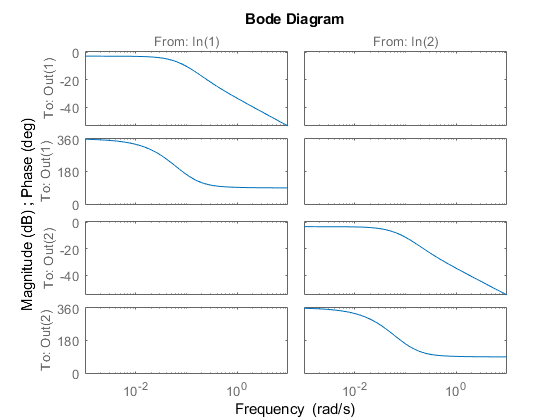

% G_tilde_alt
bode(G_tilde)

% bode(G_tilde_alt)

### 3.2.2 | Design decoupled PI controller

% Given design criteria
p_m = pi/3; % phi_m [rad]
% w_cd = 0.1; % omega_c,d minphase [rad/s] 
w_cd = 0.02; % omega_c,d nonminphase [rad/s] 

g11 = G_tilde(1,1);
g22 = G_tilde(2,2);

[m11,p11] = bode(g11, w_cd); % Amplitude and phase of system at w_cd
[m22,p22] = bode(g22, w_cd); % Amplitude and phase of system at w_cd

T11 = (1/w_cd)*tan(-pi + pi/2 + p_m - deg2rad(p11)); 
T22 = (1/w_cd)*tan(-pi + pi/2 + p_m - deg2rad(p22));

l11 = g11*(1 + 1/(s*T11));
l22 = g22*(1 + 1/(s*T22));

[m1, p1] = bode(l11,w_cd);
[m2, p2] = bode(l22,w_cd);

K1 = 1/m1;
K2 = 1/m2;

f1 = K1*(1 + 1/(s*T11));
f2 = K2*(1 + 1/(s*T22));

F_tilde = minreal([f1, 0; 0, f2])


F_tilde =
 
  From input 1 to output...
       0.751 s + 0.02517
   1:  -----------------
               s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       0.8465 s + 0.02655
   2:  ------------------
               s
 
Continuous-time transfer function.



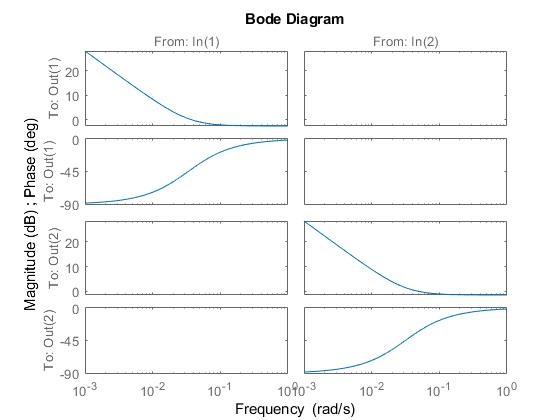

bode(F_tilde)


% W_1 = minreal(W_1*((10*w_cd)/(s+10*w_cd)))
F = minreal(W_1*F_tilde)


F =
 
  From input 1 to output...
       -0.751 s - 0.02517
   1:  ------------------
               s
 
       0.1314 s + 0.004404
   2:  -------------------
         s^2 + 0.09089 s
 
  From input 2 to output...
       0.1048 s + 0.003288
   1:  -------------------
         s^2 + 0.08582 s
 
       -0.8465 s - 0.02655
   2:  -------------------
                s
 
Continuous-time transfer function.



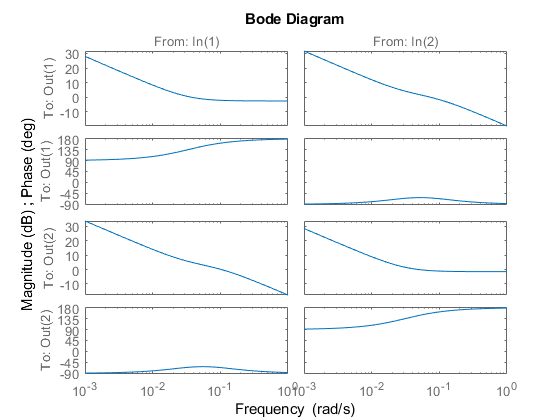

bode(F)

### 3.2.3 | Sensitivity & Complimentary Sensitivity

I = eye(size(G));
L = minreal(G*F);
L(1,2) = 0; 
L(2,1) = 0;

L


L =
 
  From input 1 to output...
       -0.01568 s^3 - 0.003296 s^2 + 0.0001246 s + 7.287e-06
   1:  -----------------------------------------------------
           s^4 + 0.2278 s^3 + 0.01682 s^2 + 0.0003983 s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       -0.0153 s^3 - 0.003184 s^2 + 0.0001274 s + 6.655e-06
   2:  ----------------------------------------------------
           s^4 + 0.2236 s^3 + 0.01609 s^2 + 0.000366 s
 
Continuous-time transfer function.




S = minreal(inv(minreal(I + L)));
T = minreal(S*L);


[Gm,Pm,wp,wc] = margin(L(1,1)) % Phase margin, amplitude margin, and corresp. freqs. of G_d

Gm = 2.4957

Pm = 59.9998

wp = 0.0613

wc = 0.0200

[Gm,Pm,wp,wc] = margin(L(2,2)) % Phase margin, amplitude margin, and corresp. freqs. of G_d

Gm = 2.4862

Pm = 59.9998

wp = 0.0607

wc = 0.0200

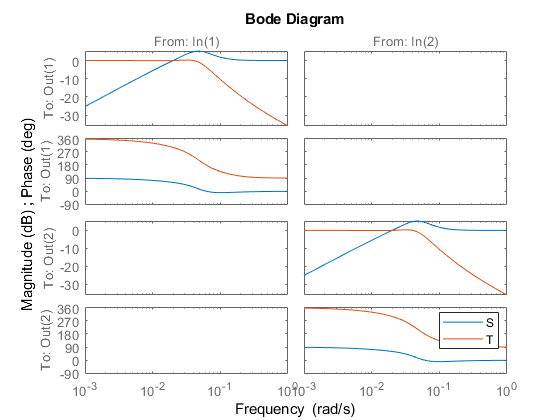


bode(S,T)
legend

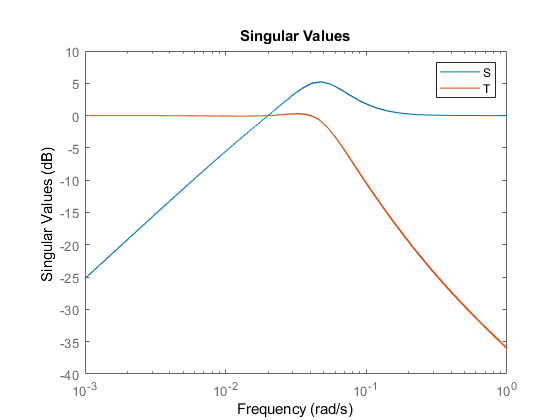

% Singular values
sigma(S, T)
legend

max(sigma(S),[],2)

ans =     1.8315
    1.8241


max(sigma(T),[],2)

ans =     1.0381
    1.0302


### 3.2.4 | Closed Loop Simulation

closedloop

% %%%% Saves prior plot as pdf filling up page %%%%
% set(1, 'PaperPosition', [0 0 5 5]); %Position plot at left hand corner with width 5 and height 5.
% set(1, 'PaperSize', [5 5]); %Set the paper to have width 5 and height 5.
% saveas(1, 'test', 'pdf')
% %%%% Saves prior plot as pdf filling up page %%%%